f0 = 24;
fm = 200;
fe = 2200;
t = 0:1/fe:800/fe

t =          0    0.0005    0.0009    0.0014    0.0018    0.0023    0.0027    0.0032    0.0036    0.0041    0.0045    0.0050    0.0055    0.0059    0.0064    0.0068    0.0073    0.0077    0.0082    0.0086    0.0091    0.0095    0.0100    0.0105    0.0109    0.0114    0.0118    0.0123    0.0127    0.0132    0.0136    0.0141    0.0145    0.0150    0.0155    0.0159    0.0164    0.0168    0.0173    0.0177    0.0182    0.0186    0.0191    0.0195    0.0200    0.0205    0.0209    0.0214    0.0218    0.0223



x = cos(2*pi*f0*t)

x =     1.0000    0.9977    0.9906    0.9789    0.9626    0.9418    0.9166    0.8871    0.8534    0.8157    0.7741    0.7290    0.6804    0.6286    0.5738    0.5164    0.4565    0.3945    0.3307    0.2653    0.1986    0.1310    0.0628   -0.0057   -0.0742   -0.1423   -0.2098   -0.2762   -0.3414   -0.4050   -0.4667   -0.5261   -0.5832   -0.6374   -0.6887   -0.7367   -0.7813   -0.8222   -0.8593   -0.8923   -0.9211   -0.9456   -0.9657   -0.9812   -0.9921   -0.9984   -0.9999   -0.9968   -0.9890   -0.9765


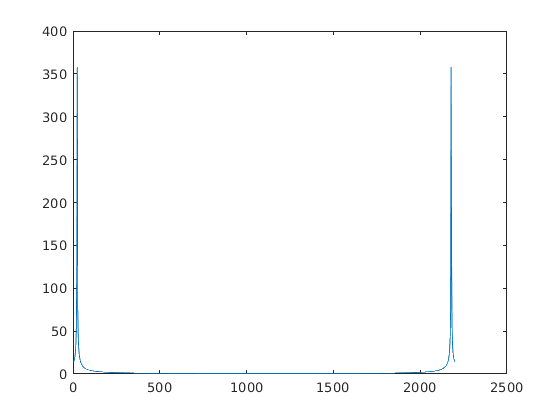


fa = abs(fft(x));

fx = fftshift(fa);

figure(1);
plot((0:1/800:1)*fe,fa)

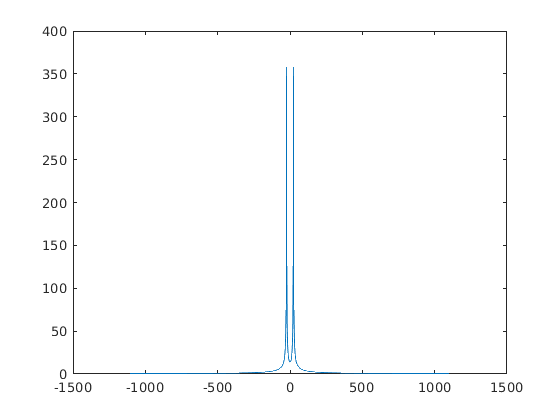

plot((((0:1/800:1)-0.5)*fe),fx)


y = cos(2*pi*fm*t);

disp(size(x));

     1   801



disp(size(y));

     1   801




z = x.*y;

%subplot(3,1,1),plot(x);
%subplot(3,1,2),plot(y);
%subplot(3,1,3),plot(z);
disp("------------------")

------------------



fx = fftshift(abs(fft(x)));
plot((((0:1/800:1)-0.5)*fe),fx)

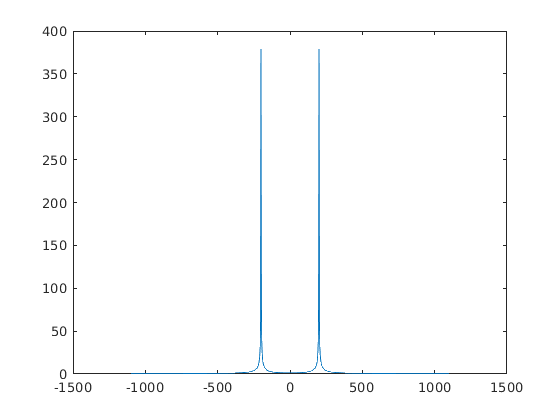

fy = fftshift(abs(fft(y)));
plot((((0:1/800:1)-0.5)*fe),fy)

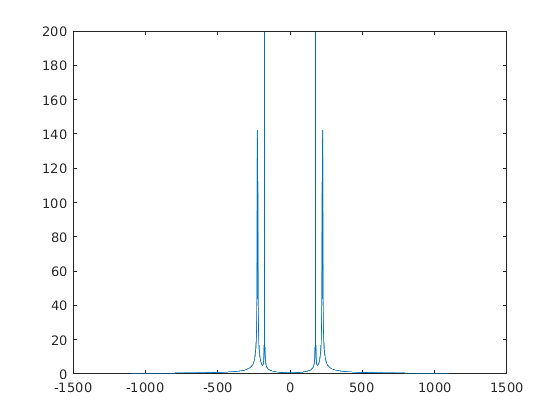

fz = fftshift(abs(fft(z)));
plot((((0:1/800:1)-0.5)*fe),fz)


disp("------------------")

------------------


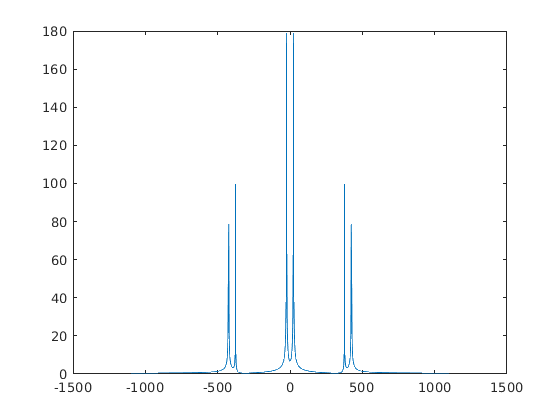


d = z.*y;
fd = fftshift(abs(fft(d)));
plot((((0:1/800:1)-0.5)*fe),fd)


s = z./y;
fs = fftshift(abs(fft(s)));
plot((((0:1/800:1)-0.5)*fe),fs)

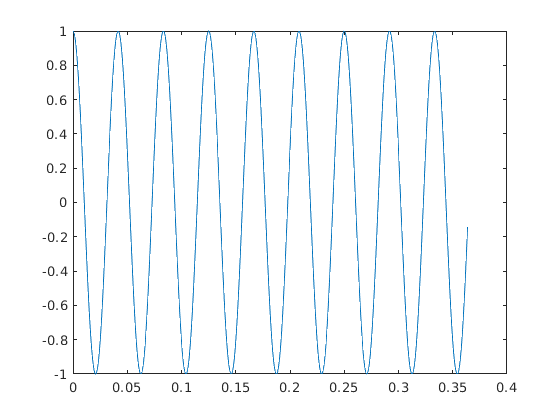


plot(t,s)

plot(t,x);